clc; close all; clear all;

## Problem 3. 

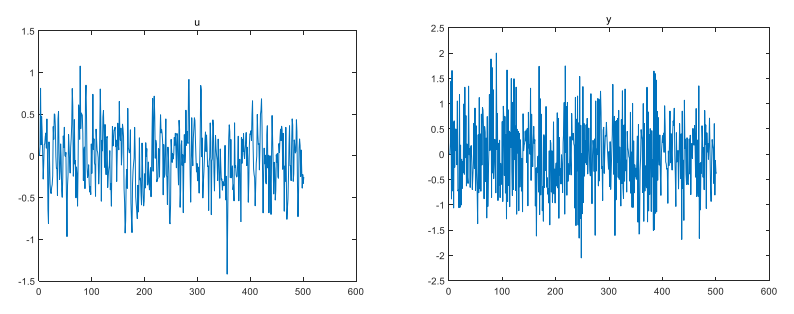

위 그림과 같이 시계열 데이터를 표현하는 운동모델이 ARX구조를 따른다고 가정할 때 아래의 문제를 푸시오.

### Problem 3-1

모델의 차수에 따른 Regressor matrix와 output vector를 정의해라

ARX model : $A\left(q^{-1} \right)y\left(k\right)=B\left(q^{-1} \right)u\left(k\right)+e\left(k\right)$


$$y(k) = -a_1y(k-1) -a_2y(k-2) - \cdots -a_my(k-m) + b_1u(k-1) + b_2u(k-2) + \cdots + b_nu(k-n)+ e(k)$$



$$A(q^{-1}) = 1 + a_1q^{-1} + \cdots + a_mq^{-m}$$



$$B(q^{-1}) = b_1q^{-1} + b_2q^{-2} + \cdots + b_nq^{-n}$$


#### Regressor matrix $\Phi =\left\lbrack \begin{array}{cccccc}
y\left(k-1\right) & \cdots  & y\left(k-m\right) & u\left(k-1\right) & \cdots \; & u\left(k-n\right)\\
y\left(k\right) & \cdots \; & y\left(k-m+1\right) & u\left(k\right) & \cdots  & u\left(k-n+1\right)\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots \\
 &  &  &  &  & 
\end{array}\right\rbrack$

#### Parameter vector $\theta =\left\lbrack \begin{array}{c}
-a_1 \\
\vdots \\
-a_m \\
b_1 \\
\vdots \\
b_n 
\end{array}\right\rbrack$

따라서 $\hat{\theta} = (\Phi^T\Phi)^{-1}\Phi Y$

### Problem 3-2

모델의 order $(n=1,2,\ldots6)$에 따른 학습모델과 **MSE(Mean Square Error)**의 크기를 비교하시오. 이를 통해 가장 적합한 모델이 무엇인지 논의하시오.

warning('off', 'all');
% 결과 가독성이 좋지 않아서 경고 문구 제외

Data = load("Prob3.mat");
model_order = 1:1:6;                % The order of model
MSE_matrix = zeros([length(model_order), length(model_order)]);
AIC_matrix = zeros([length(model_order), length(model_order)]);
BIC_matrix = zeros([length(model_order), length(model_order)]);

for input_order = model_order
    for output_order = model_order
        [MSE, error] = mean_square_error(Data, input_order, output_order);
        MSE_matrix(input_order, output_order) = MSE;
        AIC_matrix(input_order, output_order) = akaike_info_criterion(Data, input_order, output_order, error);
        BIC_matrix(input_order, output_order) = bayesian_info_criterion(Data, input_order, output_order, error);
    end
end
[value, index] = min(MSE_matrix)

value = 1.0e-15 *

    0.3377    0.1680    0.4743    0.1978    0.3721    0.2211


index =      4     1     1     1     1     1


[val, idx] = min(value)

val = 1.6800e-16

idx = 2

[theta, A_q, B_q] = least_square(Data, 1, 2)

theta =    -0.8000
   -0.0000
    2.0000


A_q =    -0.8000   -0.0000


B_q = 2

즉, $B(q^{-1})$는 **1차** $A(q^{-1})$는 **2차 시스템 모델**이 가장 MSE가 작은 모습을 보여준다.

따라서 가장 적합한 모델은


$$A(q^{-1})= 1 + 0.8q^{-1} + (-2.2551e-16 )q^{-2}$$



$$B(q^{-1}) = 2q^{-1}$$


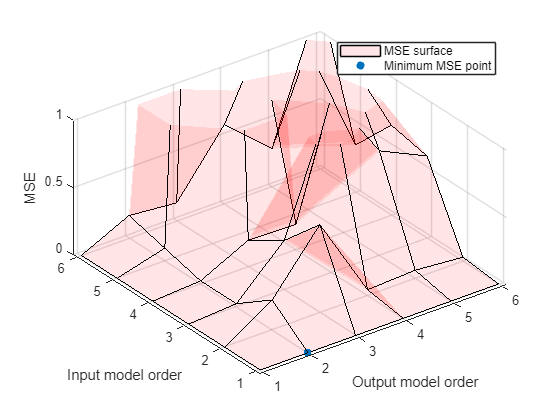

[rows, cols] = size(MSE_matrix);
[X, Y] = meshgrid(1:cols, 1:rows);
fig1 = figure(1);
MSE = surf(X, Y, MSE_matrix,'FaceAlpha', 0.1, 'FaceColor','flat');
MSE.FaceColor = "red";
xlim([0.9, 6.1]); ylim([0.9, 6.1]); zlim([0, 1]);
xlabel("Output model order"); ylabel("Input model order"); zlabel("MSE");
view([-36.900 48.000])
hold on
Minpoint = scatter3(2, 1, val, 'filled', 'LineWidth', 3);
legend([MSE, Minpoint], {"MSE surface", "Minimum MSE point"}, "Location","northeast")
hold off

***MATLAB function comparison***

Z = [Data.y, Data.u];
Aq = 2;
Bq = 1;
IOdelay = 1;
theta_ls = arx(Z, [Aq, Bq, IOdelay], 'Ts', 0.1)

theta_ls =
이산시간 ARX 모델: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 + 0.8 z^-1 - 9.622e-17 z^-2 
                                       
  B(z) = 2 z^-1                        
                                       
샘플 시간: 0.1 seconds
  
파라미터화:
   다항식 차수:   na=2   nb=1   nk=1
   자유 계수의 개수: 3
   파라미터 및 그 불확실성을 얻으려면 "polydata", "getpvec", "getcov"를 사용하십시오.

상태:                                    
시간 영역 데이터 "Z"에 대해 ARX을(를) 사용하여 추정되었습니다.
추정 데이터에 피팅: 100%(예측 중점)                
FPE: 2.184e-32, MSE: 2.141e-32         
 
모델 속성


A_q = [1, -A_q];
sys = tf([0, B_q], A_q, 0.1, 'Variable', 'z^-1')

sys =
 
             2 z^-1
  -----------------------------
  1 + 0.8 z^-1 + 2.255e-16 z^-2
 
샘플 시간: 0.1 seconds
이산시간 전달 함수입니다.
모델 속성


위의 시스템 모델을 통해서 MATLAB 내장 함수로 얻은 ARX 모델과 직접 구현한 LSM으로 도출한 결과가 매우 유사한 것을 확인할 수 있다.

현재 구한 `A_q는 ARX 모델에서 `$1-A(q^{-1})$의 계수를 의미한다. 그리고 `B_q는 `$B(q^{-1})$가 상수항이 없다는 가정 하에서 LSM이 사용됐기에 $B(q^{-1})=[0,$`B_q`$]$, $A(q^{-1}) = [1,$`-A_q`$]$라고 할 수 있다.

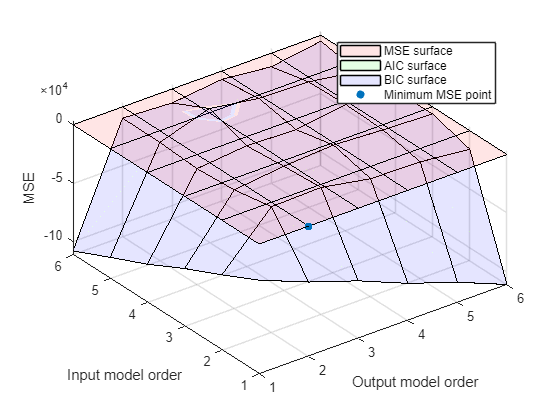

MSE = surf(X, Y, MSE_matrix,'FaceAlpha', 0.1, 'FaceColor','flat');
MSE.FaceColor = "red";
hold on
AIC = surf(X, Y, AIC_matrix, 'FaceAlpha', 0.1, 'FaceColor', 'flat');
AIC.FaceColor = "green";
BIC = surf(X, Y, BIC_matrix, 'FaceAlpha', 0.1, 'FaceColor','flat');
BIC.FaceColor = "blue";
% xlim([0.9, 6.1]); ylim([0.9, 6.1]); zlim([0, 1]);
xlabel("Output model order"); ylabel("Input model order"); zlabel("MSE");
view([-36.900 48.000])
hold on
Minpoint = scatter3(2, 1, val, 'filled', 'LineWidth', 3);
legend([MSE, AIC, BIC, Minpoint], {"MSE surface", "AIC surface", "BIC surface", "Minimum MSE point"}, "Location","northeast");
hold off

AIC와 BIC를 이용해서 model criterion을 적용하려 했지만, AIC, BIC의  항에 error 제곱이 매우 작아서 전체적으로 값이 매우 작아 판단하기 어려운 것을 확인할 수 있었다.

% 1행과 1열의 ERROR 값이 매우 작은 것을 확인할 수 있다.
MSE_matrix

MSE_matrix =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.2227    0.6552    0.0421    0.0595    0.0277
    0.0000    0.0237    0.3660    1.3075    0.7777    0.6116
    0.0000    0.0234    0.1983    0.1884    1.3431    0.6698
    0.0000    0.0961    8.0740    1.3861    1.1985    0.3516
    0.0000    0.1683    0.1347    0.5900    0.2816    1.2768


그래서 figure(1)의 MSE surface에서 가장 작은 값을 가졌던 $B(q^{-1})$ **1차,** $A(q^{-1})$ **2차 시스템 모델**이 비교적 덜 복잡하고 error가 가장 작아 적합하다고 결론지었다.

### Problem 3-3

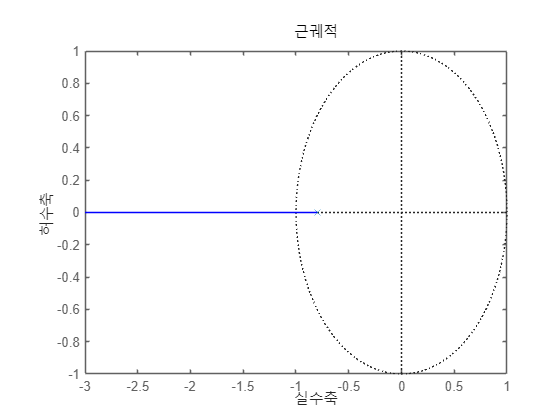

% discrete_sys_rlocus(data, input_order, output_order)
discrete_sys_rlocus(Data, 1, 1)

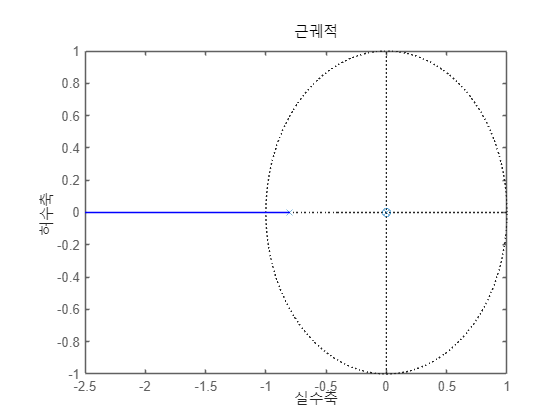

discrete_sys_rlocus(Data, 1, 2)

discrete_sys_rlocus(Data, 1, 3)

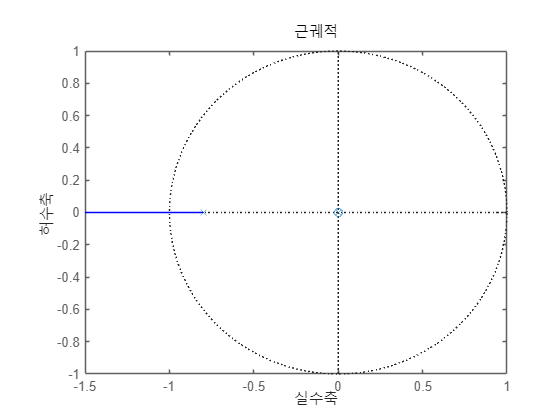

discrete_sys_rlocus(Data, 1, 4)

discrete_sys_rlocus(Data, 1, 5)

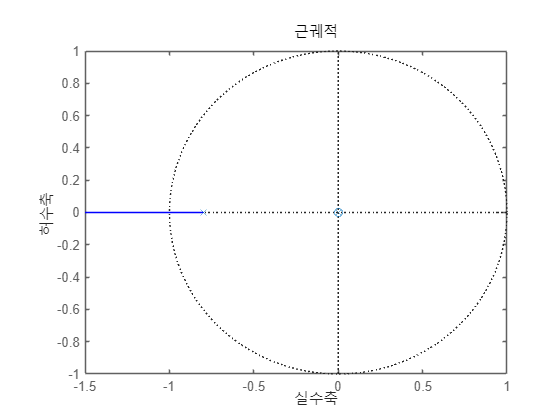

discrete_sys_rlocus(Data, 1, 6)

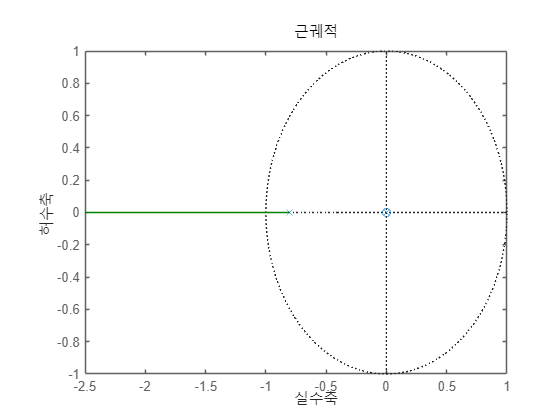

discrete_sys_rlocus(Data, 2, 1)

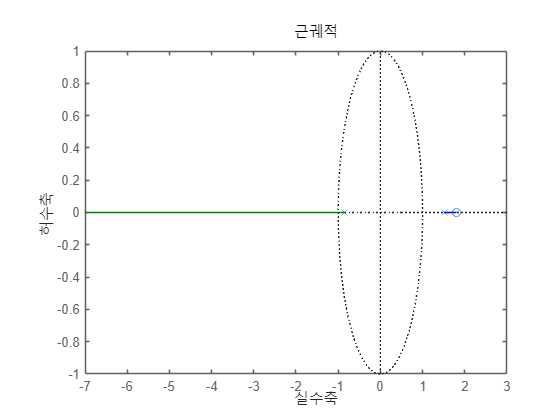

discrete_sys_rlocus(Data, 2, 2)

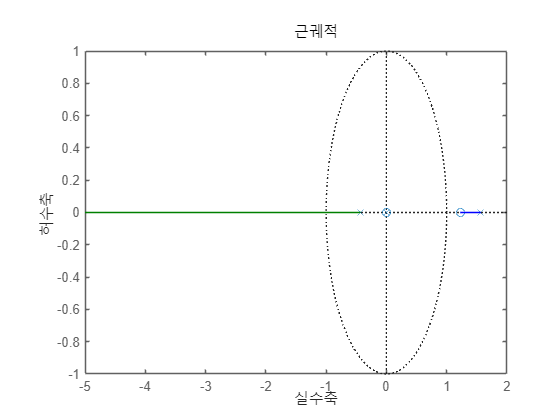

discrete_sys_rlocus(Data, 2, 3)

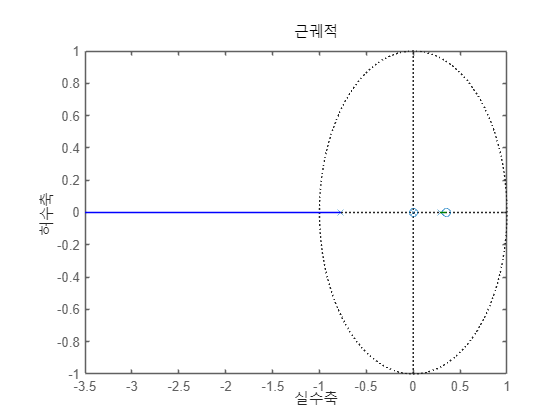

discrete_sys_rlocus(Data, 2, 4)

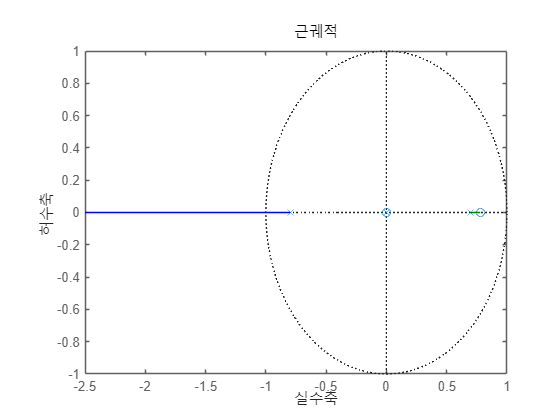

discrete_sys_rlocus(Data, 2, 5)

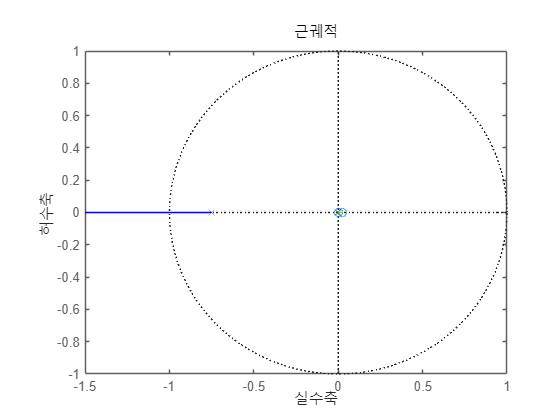

discrete_sys_rlocus(Data, 2, 6)

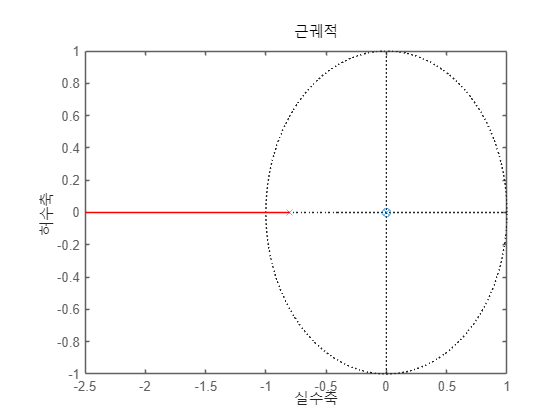

discrete_sys_rlocus(Data, 3, 1)

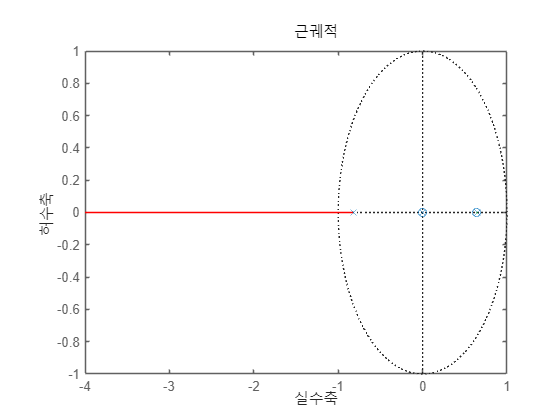

discrete_sys_rlocus(Data, 3, 2)

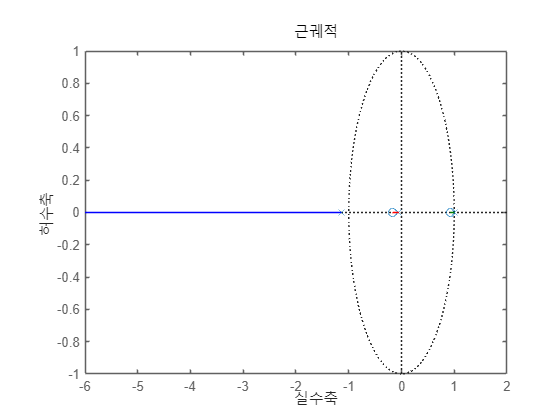

discrete_sys_rlocus(Data, 3, 3)

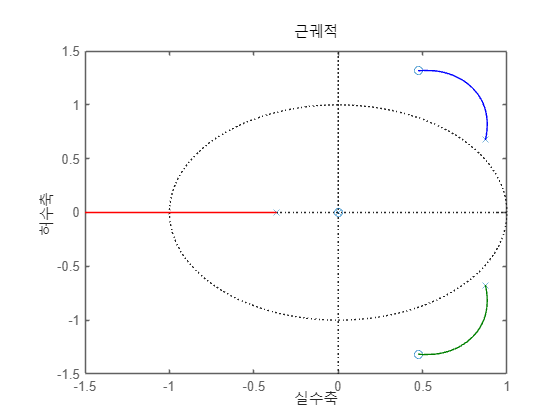

discrete_sys_rlocus(Data, 3, 4)

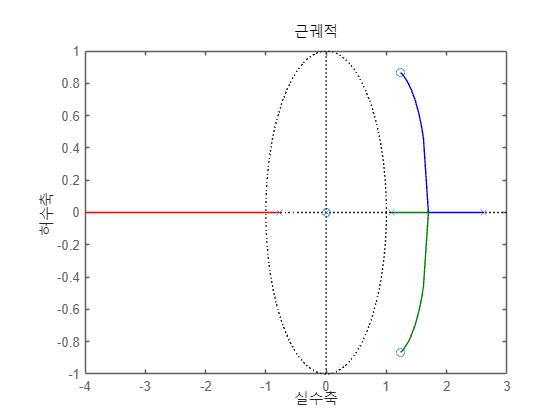

discrete_sys_rlocus(Data, 3, 5)

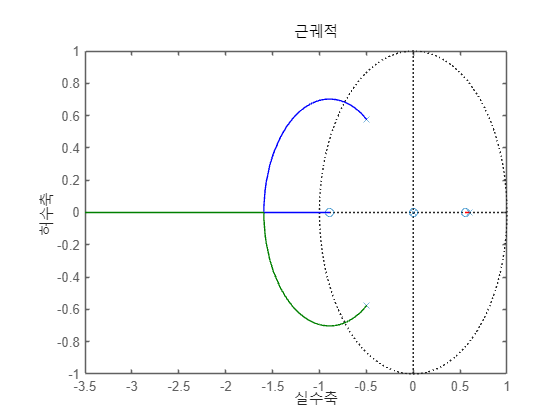

discrete_sys_rlocus(Data, 3, 6)

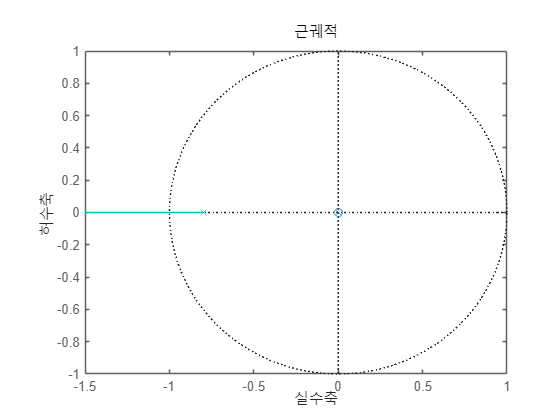

discrete_sys_rlocus(Data, 4, 1)

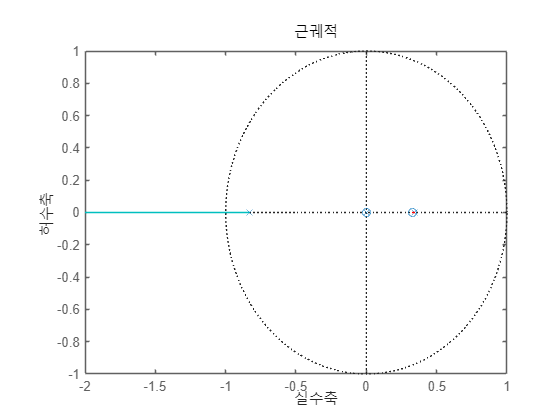

discrete_sys_rlocus(Data, 4, 2)

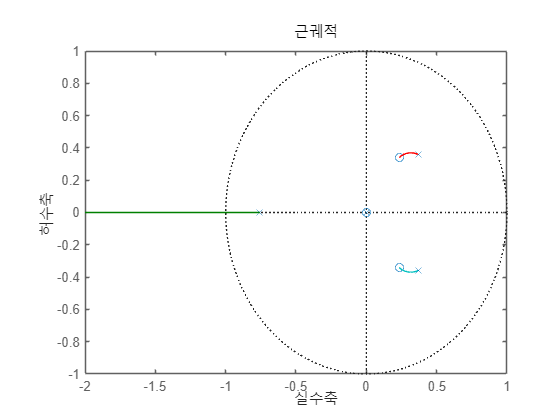

discrete_sys_rlocus(Data, 4, 3)

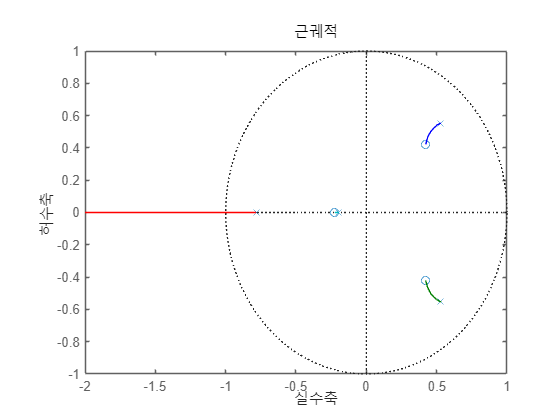

discrete_sys_rlocus(Data, 4, 4)

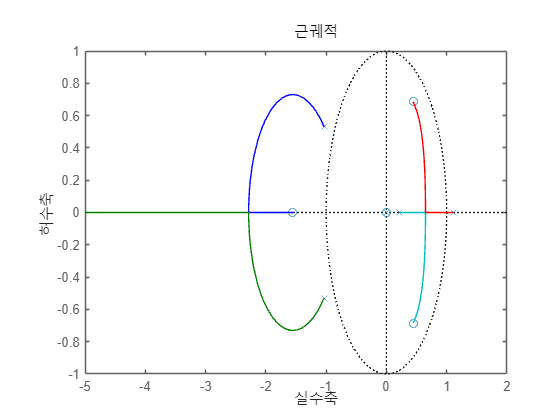

discrete_sys_rlocus(Data, 4, 5)

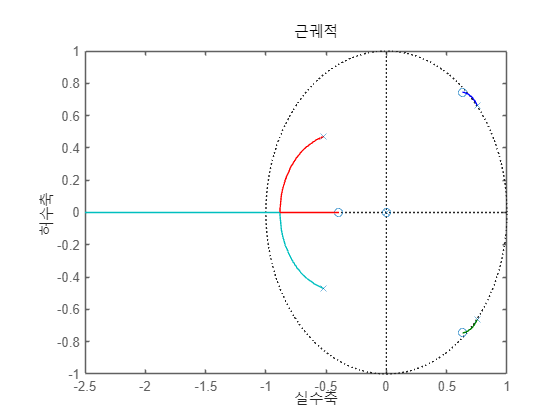

discrete_sys_rlocus(Data, 4, 6)

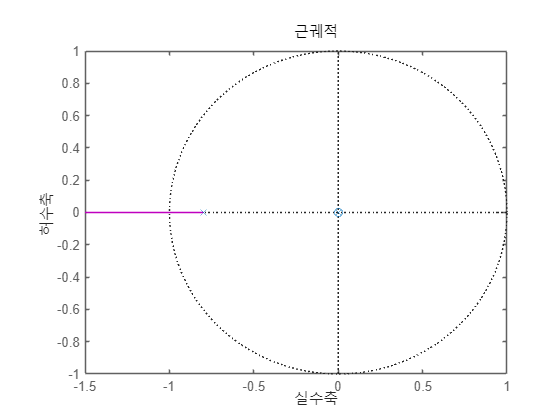

discrete_sys_rlocus(Data, 5, 1)

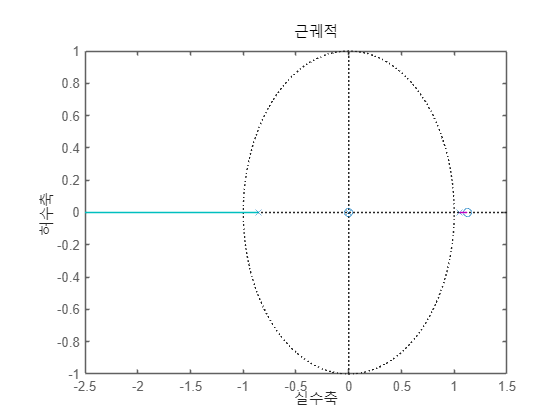

discrete_sys_rlocus(Data, 5, 2)

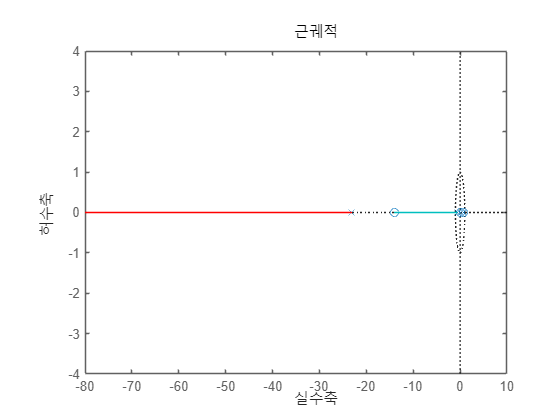

discrete_sys_rlocus(Data, 5, 3)

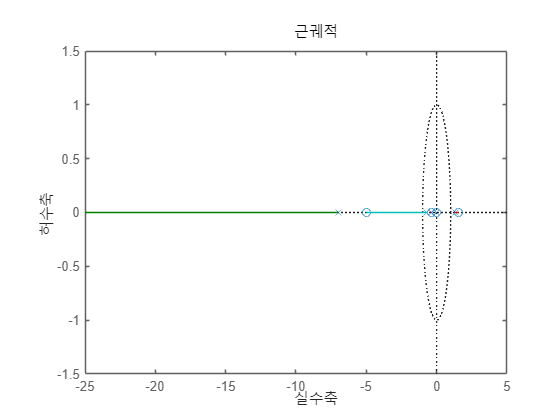

discrete_sys_rlocus(Data, 5, 4)

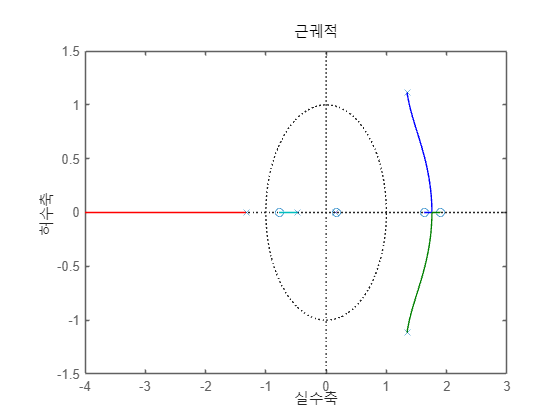

discrete_sys_rlocus(Data, 5, 5)

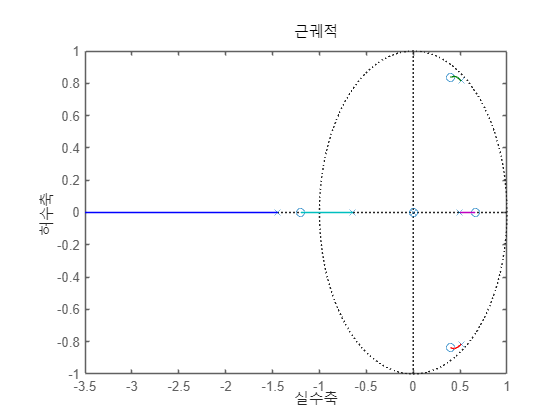

discrete_sys_rlocus(Data, 5, 6)

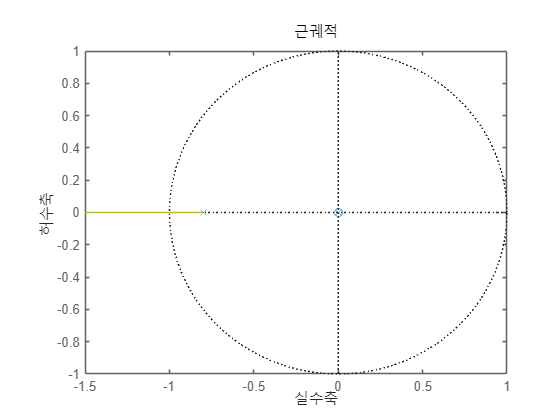

discrete_sys_rlocus(Data, 6, 1)

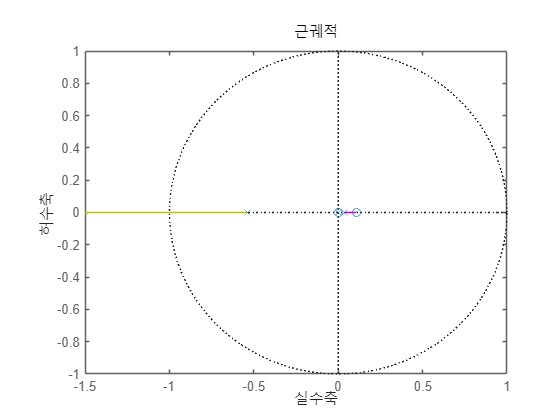

discrete_sys_rlocus(Data, 6, 2)

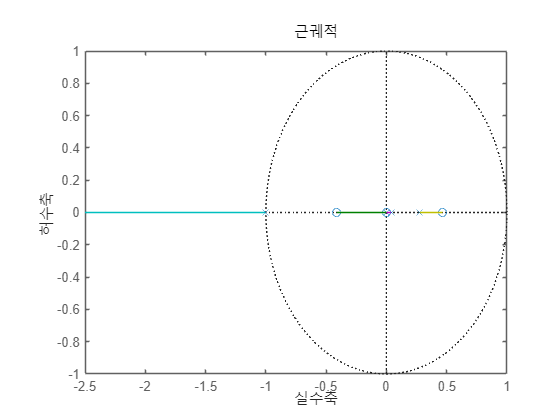

discrete_sys_rlocus(Data, 6, 3)

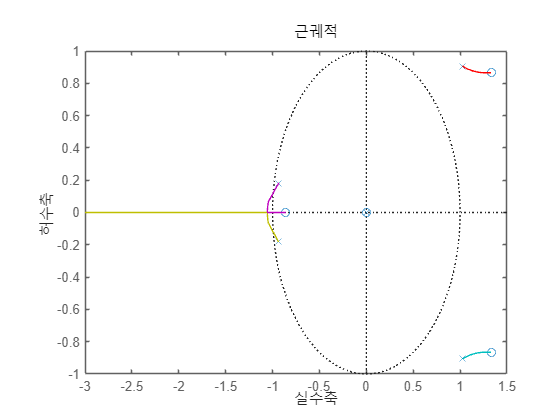

discrete_sys_rlocus(Data, 6, 4)

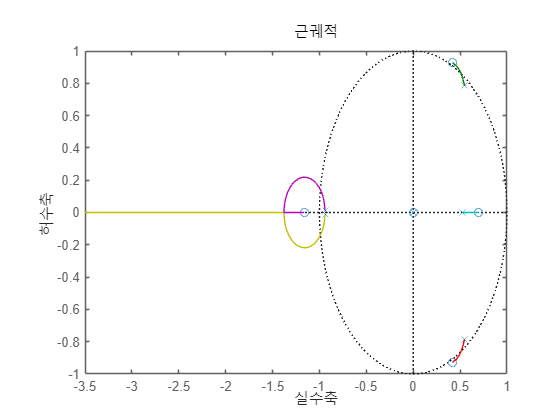

discrete_sys_rlocus(Data, 6, 5)

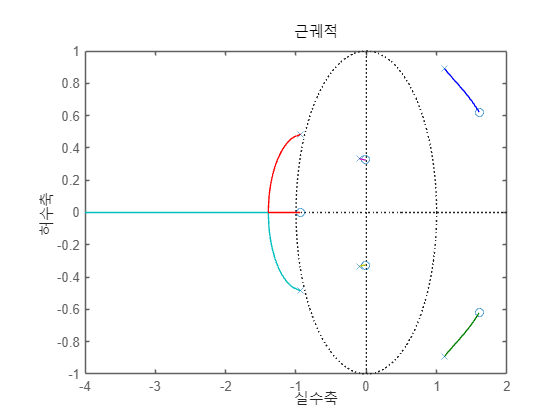

discrete_sys_rlocus(Data, 6, 6)

## Regressor matrix

function Phi = regressor_matrix(data, input_order, output_order)
    % Data와 input order, output order의 차수를 받아 regressor matrix Phi를 도출
    % data에는 input u, output y가 무조건 존재해야함
    if ~isfield(data, 'y') || ~isfield(data, 'u')
        error("Input data must contain y and u");
    end
    % Data field 확인 절차
    if length(data.y) < output_order || length(data.u) < input_order
        error("Insufficient data points in y, u");
    end
    % Data 길이 확인
    order = max(input_order, output_order);
    Phi = zeros([length(data.y)-order, input_order+output_order]);
    idx = 0;
    for i = order+1 : length(data.u)
        idx = idx + 1;
        Phi(idx, :) = [flip(data.y(i-output_order:i-1)'), flip(data.u(i - input_order:i-1)')];
    end
end

## Model derivation

function [theta, A_q, B_q] = least_square(data, input_order, output_order)
    Phi = regressor_matrix(data, input_order, output_order);
    order = max(input_order, output_order);
    Output = data.y(order+1:end);
    theta = inv(Phi'*Phi) * Phi'*Output;
    A_q = theta(1:output_order)';
    B_q = theta(output_order+1:input_order+output_order)';
end

## MSE(Mean Square Error)

function [mse, error] = mean_square_error(data, input_order, output_order)
    Phi = regressor_matrix(data, input_order, output_order);
    [theta, A_q, B_q] = least_square(data, input_order, output_order);
    output_matrix = Phi(:, 1:output_order);
    input_matrix = Phi(:, (output_order+1):(input_order+output_order));
    order = max(input_order, output_order);
    output_vector = data.y(order+1:end);
    error = output_vector - Phi*theta;
    mse = sqrt((error'*error)/length(error));
end

## AIC

function aic = akaike_info_criterion(data, input_order, output_order, error)
    % N : the number of data
    % d : the number of parameter
    Phi = regressor_matrix(data, input_order, output_order);
    N = numel(Phi);
    d = output_order + input_order + 1;
    aic = N * log10((sum(error.^2))/N) + 2*d;
end

## BIC

function bic = bayesian_info_criterion(data, input_order, output_order, error)
    % N : the number of data
    % d : the number of parameter
    Phi = regressor_matrix(data, input_order, output_order);
    N = numel(Phi);
    d = output_order + input_order + 1;
    bic = N * log10((sum(error.^2))/N) + d*log10(N);
end

## Root locus

function discrete_sys_rlocus(data, input_order, output_order)
    [theta, A_q, B_q] = least_square(data, input_order, output_order);
    A_q = [1, -A_q];
    B_q = [0, B_q];
    sys = tf(B_q, A_q, 0.1, 'Variable', 'z^-1');
    rlocus(sys);
end